clc,clear,close all

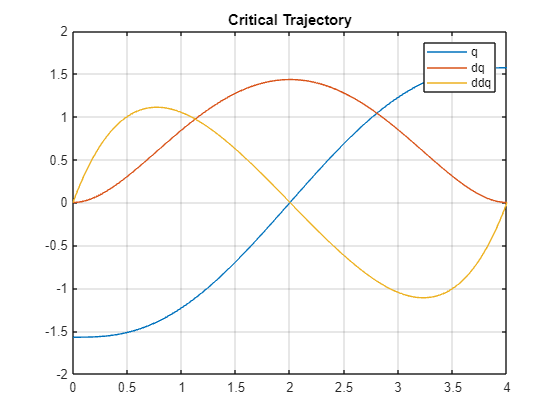

% Dynamical Model of two link Planar Manupulator 

% motor properties
amax=1.05; %[rad/s^2]
mm = [0.3, 0.3];
Im = [54e-6, 54e-6]; %[kg/m^2]
kr = [1/10,1/5];
%kr = [1,1];

%{
% link dimension
lx=[0.20 0.20]; % m
ly=[0.06 0.06]; % m
lz=[0.01 0.01]; % m
%}

% link dimension
lx=[0.170, 0.148]; % m
ly=[0.06 0.06]; % m
lz=[0.007 0.007]; % m



%material properties
density=2660; % [kg/m3] AW 5083 alloy
%rho=(density*1000)/100^3; %[g/cm3]
rho = density; 

mass=[rho*lx(1)*ly(1)*lz(1) rho*lx(2)*ly(2)*lz(2)];

% simulation parameters
methods = dynlib;
Tf = 4;
t_step = 0.01;
[A, ~] = methods.criticaltrajectory(Tf, amax);
t = [0:0.01:Tf];
qd = [];

for i=1:length(t)
    qd=[qd;A'*methods.vand(t(i), 7)', A'*methods.devand(t(i),7)', A'*methods.dedevand(t(i),7)'];
end

figure
plot(t, qd);
legend('q', 'dq','ddq');
title('Critical Trajectory');
grid on;


% TODO: Friction?
F = [0.01 0; 0 0.01]; % TEMP

% Initial Values

q0 = [-pi/2;-pi/2];
dq0 = [0;0];
ddq0 = [0;0];

%controller variables
%Kp = diag([ 15 15 ]);
%Kd = diag([ 32 32 ]);

val=[1 1];
Kp=diag((val.^2)./2);
Kd=diag(val);
%wry 

[Bq, Cq, gq, q, dq] = methods.dyn(lx,ly,lz,rho,mm,Im,kr)

$$Bq = \begin{array}{l} \left(\begin{array}{cc} \frac{3747080724978270861\,\cos\left(q_{1}+2\,q_{2}\right)}{900719925474099200000}+\frac{114455742399058038817\,\cos\left(q_{1}+q_{2}\right)}{4503599627370496000000}+\frac{67915440879509458067\,\cos\left(q_{1}\right)}{900719925474099200000}+\frac{11241242174934812583\,\cos\left(q_{2}\right)}{900719925474099200000}+\frac{11289734304701277175876471838924867757}{259614842926741381426524816461004800000} & \sigma_{1}\\ \sigma_{1} & \frac{4463434392988821487\,\cos\left(q_{1}+q_{2}\right)}{281474976710656000000}+\frac{2050767153535404467\,\cos\left(q_{1}\right)}{56294995342131200000}+\frac{3747080724978270861\,\cos\left(q_{2}\right)}{900719925474099200000}+\frac{2507678150846039953091700154663962797}{259614842926741381426524816461004800000} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{3747080724978270861\,\cos\left(q_{1}+2\,q_{2}\right)}{1801439850948198400000}+\frac{185870692686879182609\,\cos\left(q_{1}+q_{2}\right)}{9007199254740992000000}+\frac{2050767153535404467\,\cos\left(q_{1}\right)}{56294995342131200000}+\frac{3747080724978270861\,\cos\left(q_{2}\right)}{450359962737049600000}+\frac{2507117382785318191579263046747162797}{259614842926741381426524816461004800000} \end{array}$$

$$Cq = \begin{array}{l} \left(\begin{array}{cc} -\frac{{\mathrm{dq}}_{2}\,\left(\frac{3747080724978270861\,\sigma_{1}}{900719925474099200000}+\frac{\sigma_{2}}{180143985094819840000}+\frac{3747080724978270861\,\sin\left(q_{2}\right)}{450359962737049600000}\right)}{2} & -\frac{101272452026439753\,\left({\mathrm{dq}}_{1}+{\mathrm{dq}}_{2}\right)\,\left(37\,\sigma_{1}+85\,\sin\left(q_{1}+q_{2}\right)+74\,\sin\left(q_{2}\right)\right)}{1801439850948198400000}\\ {\mathrm{dq}}_{1}\,\left(\frac{3747080724978270861\,\sigma_{1}}{1801439850948198400000}+\frac{\sigma_{2}}{360287970189639680000}+\frac{3747080724978270861\,\sin\left(q_{2}\right)}{900719925474099200000}\right) & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{1}+2\,q_{2}\right)\\ \sigma_{2}=1721631684449475801\,\sin\left(q_{1}+q_{2}\right) \end{array}$$

$$gq = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

$$q = \left(\begin{array}{c} q_{1}\\ q_{2} \end{array}\right)$$

$$dq = \left(\begin{array}{c} {\mathrm{dq}}_{1}\\ {\mathrm{dq}}_{2} \end{array}\right)$$

disp("B(q)=")

B(q)=


vpa(Bq, 5)

$$ans = \begin{array}{l} \left(\begin{array}{cc} 0.0041601\,\cos\left(q_{1}+2.0\,q_{2}\right)+0.025414\,\cos\left(q_{1}+q_{2}\right)+0.075401\,\cos\left(q_{1}\right)+0.01248\,\cos\left(q_{2}\right)+0.043486 & \sigma_{1}\\ \sigma_{1} & 0.015857\,\cos\left(q_{1}+q_{2}\right)+0.036429\,\cos\left(q_{1}\right)+0.0041601\,\cos\left(q_{2}\right)+0.0096592 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=0.00208\,\cos\left(q_{1}+2.0\,q_{2}\right)+0.020636\,\cos\left(q_{1}+q_{2}\right)+0.036429\,\cos\left(q_{1}\right)+0.0083202\,\cos\left(q_{2}\right)+0.0096571 \end{array}$$

disp("C(q, dq)=")

C(q, dq)=


vpa(Cq, 5)

$$ans = \begin{array}{l} \left(\begin{array}{cc} -0.5\,{\mathrm{dq}}_{2}\,\left(0.0041601\,\sigma_{1}+0.009557\,\sin\left(q_{1}+q_{2}\right)+0.0083202\,\sin\left(q_{2}\right)\right) & -0.000056218\,\left({\mathrm{dq}}_{1}+{\mathrm{dq}}_{2}\right)\,\left(37.0\,\sigma_{1}+85.0\,\sin\left(q_{1}+q_{2}\right)+74.0\,\sin\left(q_{2}\right)\right)\\ {\mathrm{dq}}_{1}\,\left(0.00208\,\sigma_{1}+0.0047785\,\sin\left(q_{1}+q_{2}\right)+0.0041601\,\sin\left(q_{2}\right)\right) & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{1}+2.0\,q_{2}\right) \end{array}$$